# 生成随机数据

在单位圆内生成一组随机点。将第一和第三象限中的点标记为属于正类， 将第二和第四象限中的点标记为属于负类。

rng(1);  % For reproducibility
n = 100; % Number of points per quadrant

r1 = sqrt(rand(2*n,1));                     % Random radii
t1 = [pi/2*rand(n,1); (pi/2*rand(n,1)+pi)]; % Random angles for Q1 and Q3
X1 = [r1.*cos(t1) r1.*sin(t1)];             % Polar-to-Cartesian conversion

r2 = sqrt(rand(2*n,1));
t2 = [pi/2*rand(n,1)+pi/2; (pi/2*rand(n,1)-pi/2)]; % Random angles for Q2 and Q4
X2 = [r2.*cos(t2) r2.*sin(t2)];

X = [X1; X2];        % Predictors
Y = ones(4*n,1);
Y(2*n + 1:end) = -1; % Labels

## 绘制数据图。

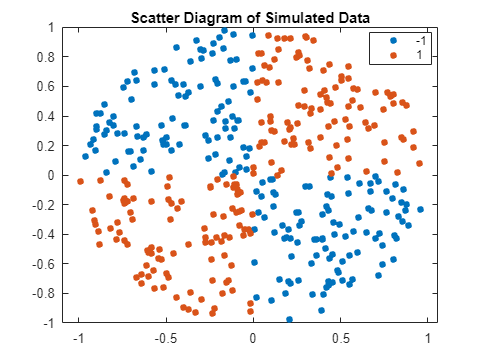

figure;
gscatter(X(:,1),X(:,2),Y);
title('Scatter Diagram of Simulated Data')